# Coursework 1

## Predicting survival in the Titanic disaster

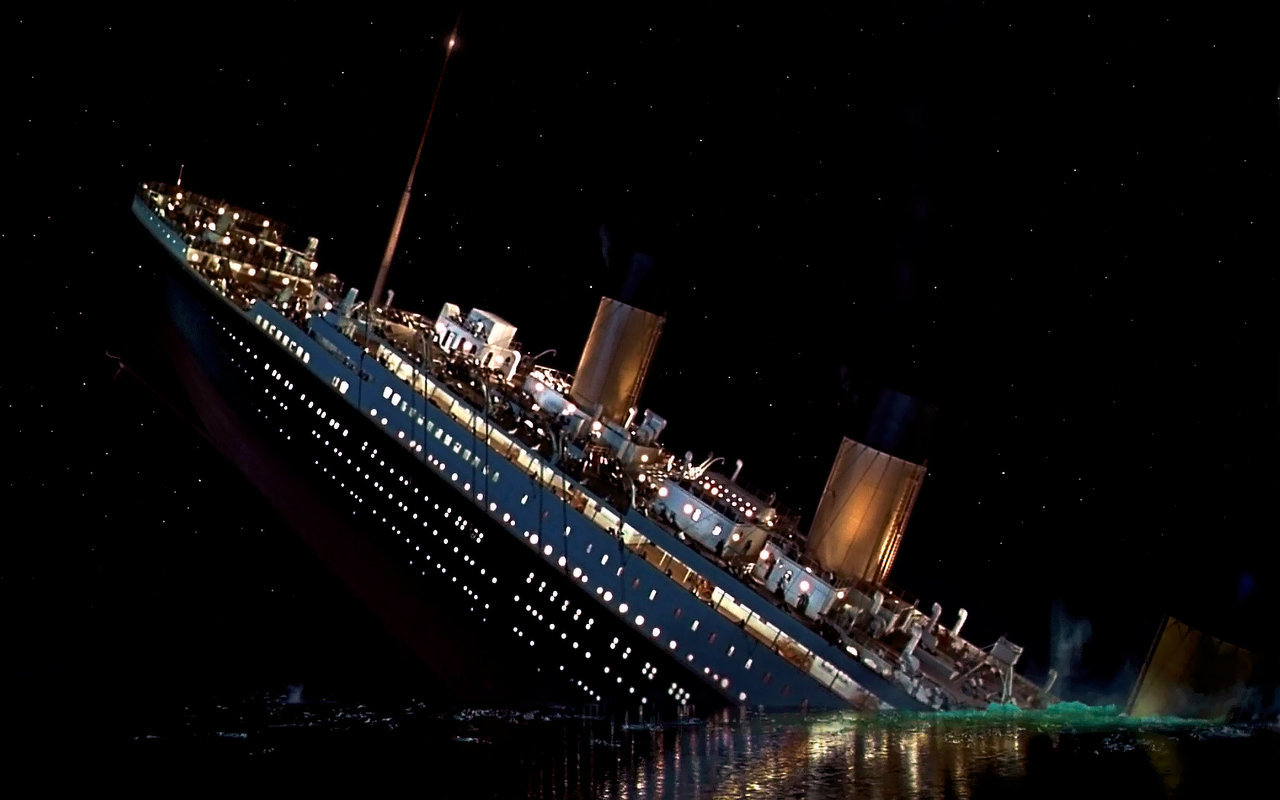

**Summary: **On 15 April 1912, the RMS Titanic ship struck an iceberg and sank. Of the estimated 2224 passengers on board over 1500 died. This led to significant changes in maritime safety regulations. With modern AI tools we can go further and ask 'what sort of passenger was most likely to survive'?  This type of information could help identify shortcomings in safety and processes.  For this coursework you will build a classifier, based on decision trees and random forests, that will predict whether or not a passenger would survive. You will report back on the key attributes that determine survival. You will be given a partial passenger list, containing multiple data points for each passenger and whether or not they survived, to train your model.  Part of the assessment will be to run the model on unseen passenger data and predict survival.

**Marks:** 25% of module mark. Marking rubric is on Moodle. Marks and feedback will be provided 15 working days after the submission deadline; each student will receive an individual copy of the marking rubric posted on Moodle by email. If required, further individual feedback is then available by requesting a one-to-one meeting.

**Submission: **MATLAB live script (.mlx) plus any functions (.m) or live functions (.mlx) files used. To be submitted via Moodle - put **ALL** your files into a single .zip archive that can be unzipped into a folder and then run.

**Deadline: **Thursday 19 March 3pm

**Estimated time required: **~40 hours

**Files: **The file passengers.csv contains a list of some of the passengers and their details (attributes).  The attributes provided are described in the file attributes.pdf.

**Note about copying code: **We may use MOSS ([http://theory.stanford.edu/~aiken/moss/](http://theory.stanford.edu/~aiken/moss/)) to check for similarity between pieces of code - both with other students and with code available online.  Please WRITE YOUR OWN CODE and do not just copy from online examples - you will get zero if you are found doing this.

## Part 1: Data analysis and plotting (25%)

To start with, make sure you can load the data and can plot it.  For example:

clc;
close all;
clear variables;

passengerData = readtable('passengers.csv')

passengerData = 1159×14 table
    pclass    survived                            name                                sex        age    sibsp    parch       ticket        fare        cabin       embarked       boat       body                 home_dest             
    ______    ________    _____________________________________________________    __________    ___    _____    _____    ____________    ______    ___________    ________    __________    ____    ___________________________________
      1          1        {'

We can then plot a pie chart of the sex of those who died:

passengerSex = passengerData.sex;
passengerSurvival = passengerData.survived;

% Produce a logical type ('true' or 'false') list indicating those who survived
survivors = (passengerSurvival == 1);

sexOfNonSurvivors = passengerSex(~survivors); %Sex of those who did not survive
maleNonSurvivors = strcmp(sexOfNonSurvivors,'male'); % Male who did not survive

### Tasks:

1. Plot two pie charts: the first should show the gender split of survivors and the second should show the gender split of all passengers.

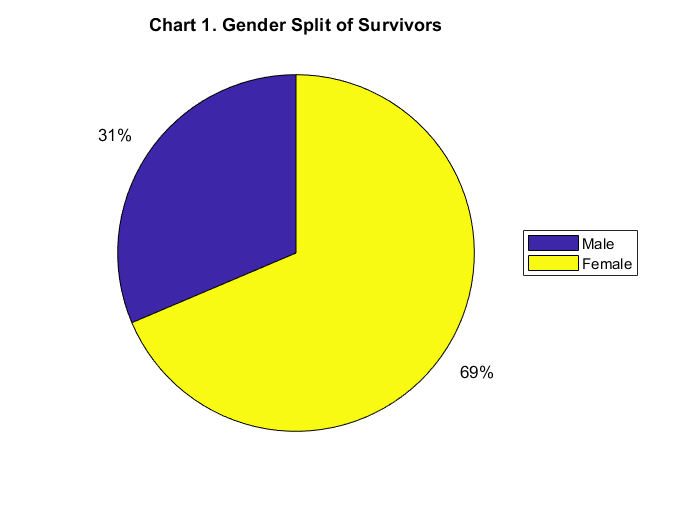

sexOfSurvivors = passengerSex(survivors); % Sex of those who survided
maleSurvivors = strcmp(sexOfSurvivors,'male'); % Male Survivors
nMaleSurvivors = sum(maleSurvivors); % Number of the male - Survivors
nFemaleSurvivors = sum(~maleSurvivors); % Number of the female - Survivors
pie([nMaleSurvivors,nFemaleSurvivors]);
legend('Male','Female','location',"eastoutside")
title('Chart 1. Gender Split of Survivors')

totalFemalePassengers = nnz(strcmp(passengerData.sex,'female'))

totalFemalePassengers = 421

totalMalePassengers = nnz(strcmp(passengerData.sex,'male'))

totalMalePassengers = 738

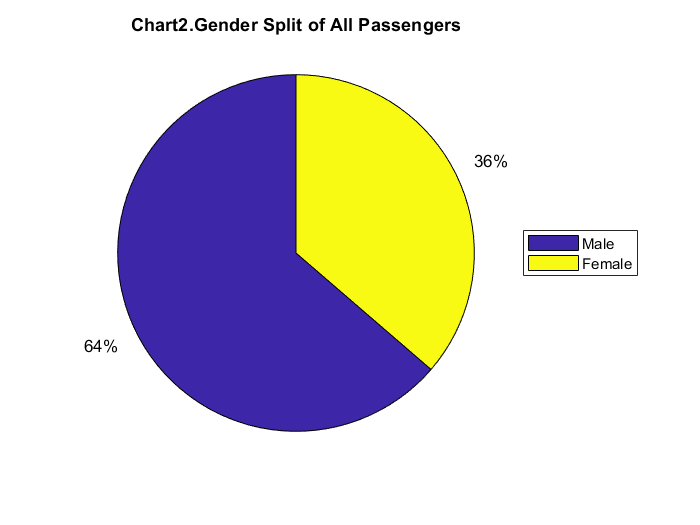

pie([totalMalePassengers,totalFemalePassengers])
legend("Male",'Female','location',"eastoutside")
title("Chart2.Gender Split of All Passengers")

nMaleNonSurvivors = sum(maleNonSurvivors); %Number of male non-survivors
nFemaleNonSurvivors = sum(~maleNonSurvivors);
nSurvivors = nnz(survivors)

nSurvivors = 446

nNonSurvivors = nnz(~survivors)

nNonSurvivors = 713

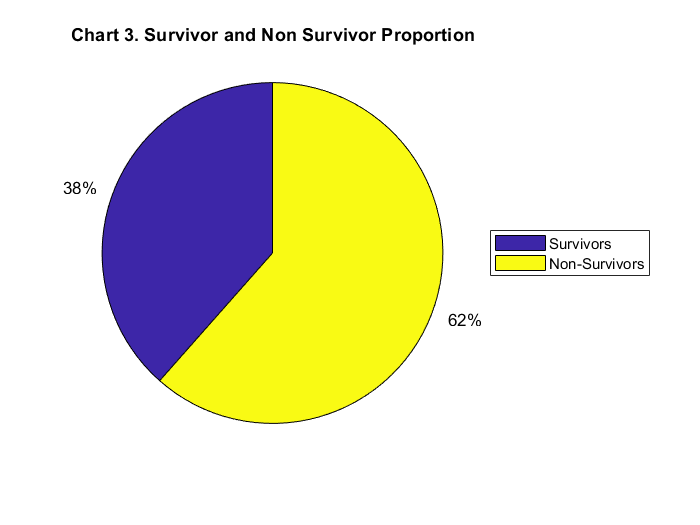

pie([nSurvivors,nNonSurvivors]);
legend('Survivors','Non-Survivors','location',"eastoutside")
title('Chart 3. Survivor and Non Survivor Proportion')

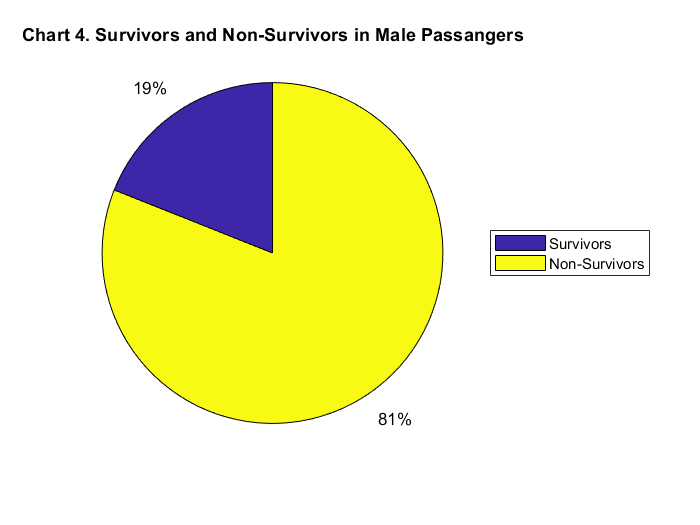

% Additional Pie Charts to Observe Survivors and Non-Survivors (according to the distribution of the sexes within themselves)
pie([nMaleSurvivors,nMaleNonSurvivors]);
legend('Survivors','Non-Survivors','location',"eastoutside")
title('Chart 4. Survivors and Non-Survivors in Male Passangers')

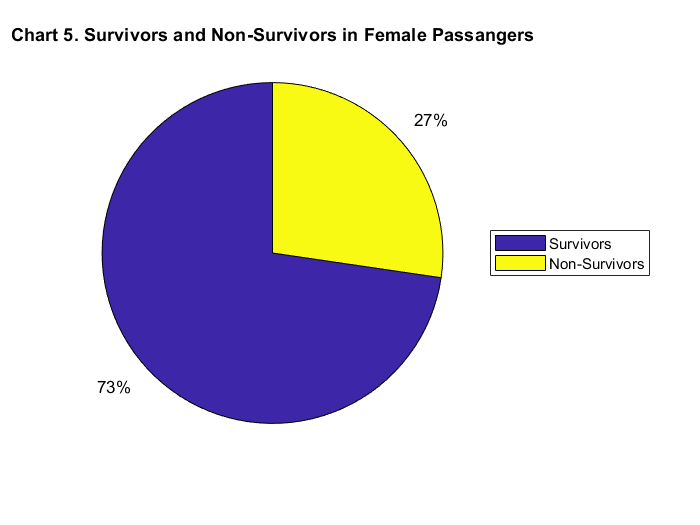

pie([nFemaleSurvivors,nFemaleNonSurvivors]);
legend('Survivors','Non-Survivors','location',"eastoutside")
title('Chart 5. Survivors and Non-Survivors in Female Passangers')

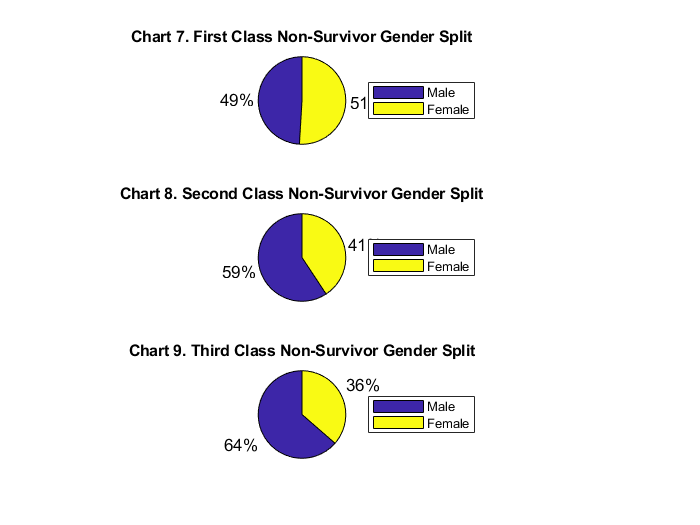

tempFirstClassAndNSurvivor = passengerData(~survivors,:).pclass == 1;  %First Class and Non-Survivors
maleFirstClassPie = nnz(strcmp(passengerData(tempFirstClassAndNSurvivor,:).sex,'male')); %First Class and Non-Survivors(males)
femaleFirstClassPie =  nnz(strcmp(passengerData(tempFirstClassAndNSurvivor,:).sex,'female')); %First Class and Non-Survivors(females)
tempSecondClassAndNSurvivor = passengerData(~survivors,:).pclass == 2;%Second Class and Non-Survivors
maleSecondClassPie = nnz(strcmp(passengerData(tempSecondClassAndNSurvivor,:).sex,'male'));
femaleSecondClassPie = nnz(strcmp(passengerData(tempSecondClassAndNSurvivor,:).sex,'female'));
tempThirdClassAndNSurvivor = passengerData(~survivors,:).pclass == 3; %Third Class and Non-Survivors
maleThirdClassPie = nnz(strcmp(passengerData(tempThirdClassAndNSurvivor,:).sex,'male'));
femaleThirdClassPie = nnz(strcmp(passengerData(tempThirdClassAndNSurvivor,:).sex,'female'));
figure,
subplot(311)
pie([maleFirstClassPie,femaleFirstClassPie]);
legend('Male','Female','location',"eastoutside")
title('Chart 7. First Class Non-Survivor Gender Split')
subplot(312)
pie([maleSecondClassPie,femaleSecondClassPie]);
legend('Male','Female','location',"eastoutside")
title('Chart 8. Second Class Non-Survivor Gender Split')
subplot(313)
pie([maleThirdClassPie,femaleThirdClassPie]);
legend('Male','Female','location',"eastoutside")
title('Chart 9. Third Class Non-Survivor Gender Split')

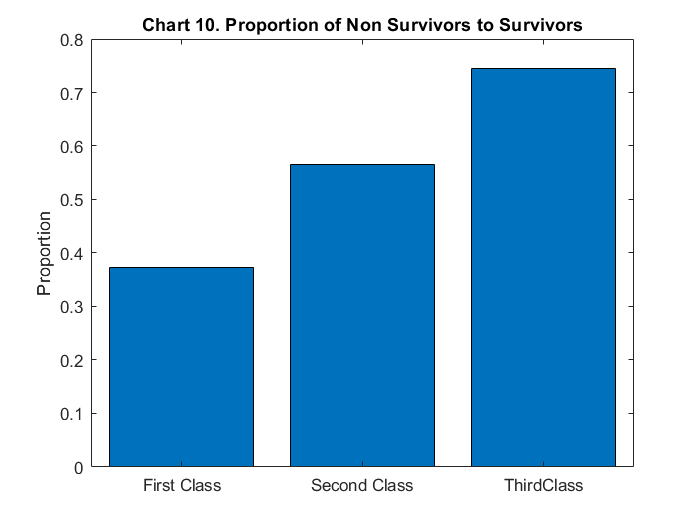

firstClassNonSurvivorBar = nnz(passengerData(~survivors,:).pclass == 1)/nnz(passengerData.pclass == 1); 
secondClassNonSurvivorBar = nnz(passengerData(~survivors,:).pclass == 2)/nnz(passengerData.pclass == 2); 
thirdClassNonSurvivorBar = nnz(passengerData(~survivors,:).pclass == 3)/nnz(passengerData.pclass == 3); 
figure,
barXaxis = categorical({'First Class','Second Class','ThirdClass'});
barYaxis = [firstClassNonSurvivorBar,secondClassNonSurvivorBar,thirdClassNonSurvivorBar];
bar(barXaxis,barYaxis);
title('Chart 10. Proportion of Non Survivors to Survivors')
ylabel('Proportion')

What trends do you observe?

***The number of the male passengers on the ships was higher than the number of the female passengers. Therefore, the death rate 62% consisted of generally men that just %19 of the total male passenger managed to survive, while this number was 73% for female passengers. Therefore, if you were a female passenger on the Titanic, you would have a more chance to be survived than male passenger.***

***In addition to gender, the type of class has somehow effects on deaths as it is seen in Chart 10. Third class has the biggest death rate (non-survivor in third class / total passenger of thirdclass), following by second class.***

***To sum up, if you were a male passenger  travelling in third class, you would probably die in that accident. On the other hand, if you were a female passenger travelling in first class, you might even play in the movie in future.***

2. Plot two histograms: the first should show of the ages of survivors and the second should show the ages of non-survivors.  You may find the following functions useful:

and

For information on how to use these function type:

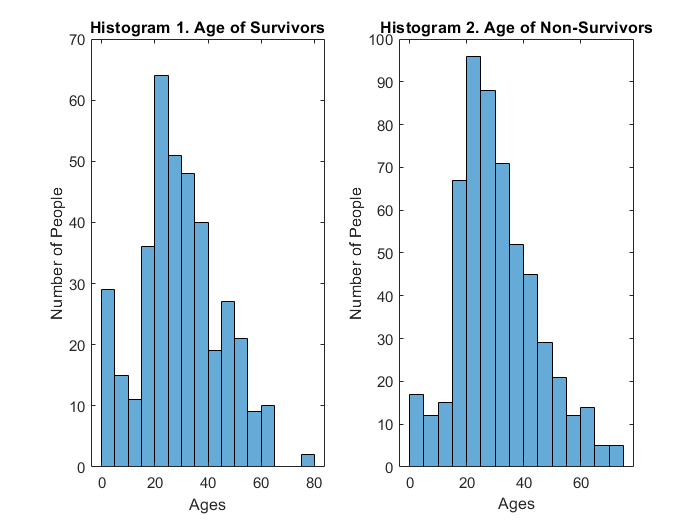

passengerAges = passengerData.age; % Ages of the total passengers
survivorsAges = passengerAges(survivors); % Ages of the survivors
nonSurvivorsAges = passengerAges(~survivors); % Ages of the Non-Survivors
figure,
subplot(121)
histogram(survivorsAges)
title('Histogram 1. Age of Survivors')
xlabel('Ages')
ylabel('Number of People')
subplot(122)
histogram(nonSurvivorsAges)
title('Histogram 2. Age of Non-Survivors')
ylabel('Number of People')
xlabel('Ages')

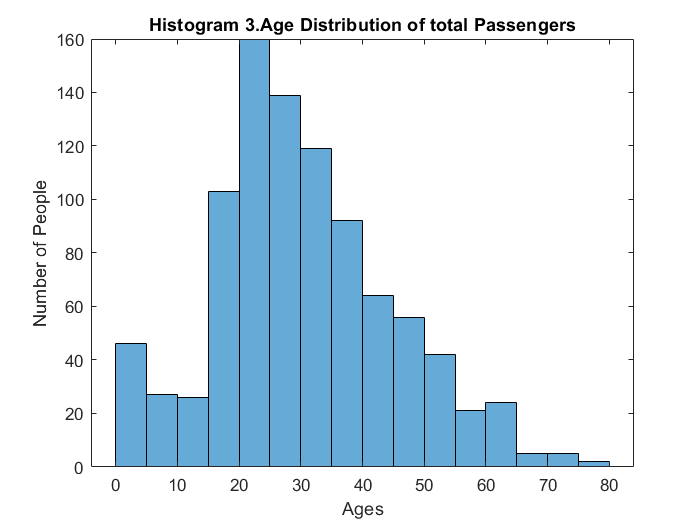

figure,
histogram(passengerData.age)
title('Histogram 3.Age Distribution of total Passengers')
ylabel('Number of People')
xlabel('Ages')

What trends do you observe from these histograms?

***Actually, these histograms gives us uniform distribution of the ages.  I needed to add extra histogram to total age distribution of the passengers. I think first two histograms are sensible, I mean they shows same patterns in big picture, but if we pick age range sample by sample, we can observe dramatic difference, and the total  age distribution is between 20 and 40 therefore, we except more death in that age range. In addition to this, the children between 5-15 ages managed to survive in large, while the elder people between 65 and 75 did not managed to survive.***

***Note : We will discuss it later but , I think (I might be wrong ) age is not very useful to use for prediction of future ( even it has significant importance to predict in next sections) . The reason, age distribution of the next ship might be difference, for example  the all passengers might be retired people. In our histogram, we can say that people between 70 and 80 almost all  managed to survive so, model could be deceptive. Therefore, the model we will use for prediction in that coursework will be effective on data that has average age point between 20 and 40. ***

3. Many passenger entries in the dataset do not contain entries in all fields: for example 'age' is often missing. Calculate the proportion of passengers in each of first, second and third class whose age data is not known and plot this data in bar chart.  The x-axis should be 'class of travel' and the y-axis should be 'proportion of passengers with missing age data'. Note that blank entries in the raw CSV file (if opened in Excel) correspond to `NaN` entries in MATLAB.  You might find the following function useful:

nanAgeArray = isnan(passengerAges) ; % NaN values in ages
firstClassProp = nnz((passengerData.pclass == 1 ) & (nanAgeArray == 1)) / nnz((passengerData.pclass == 1 )) % Proportion of Nan-Age Values in first class

firstClassProp = 0.1232

%{

Other Method
firstClassMatrix = passengerData.pclass == 1
detectionOfNanNumber = nnz(firstClassMatrix .* nanAgeArray) ----> Result == 35
nFirstClass = nnz(passengerData.pclass == 1 ) -----> Result == 284
propFirstClass = detectionOfNanNumber / nFirstClass -----> Result == (35/284 = 0.1232)

%}

secondClassProp = nnz((passengerData.pclass == 2 ) & (nanAgeArray == 1)) / nnz((passengerData.pclass == 2 )) % Proportion of Nan-Age Values in second class

secondClassProp = 0.0605

thirdClassProp = nnz((passengerData.pclass == 3 ) & (nanAgeArray == 1)) / nnz((passengerData.pclass == 3 )) % Proportion of Nan-Age Values in third class

thirdClassProp = 0.2839

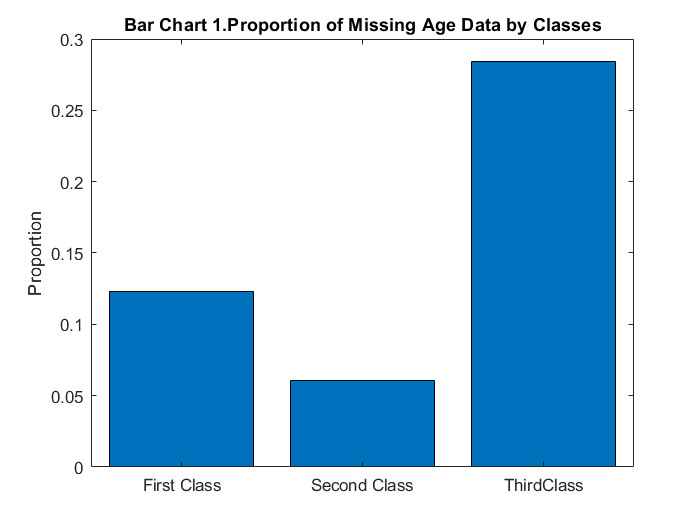

barXaxis = categorical({'First Class','Second Class','ThirdClass'});
barYaxis = [firstClassProp secondClassProp thirdClassProp];
figure,
bar(barXaxis,barYaxis)
title('Bar Chart 1.Proportion of Missing Age Data by Classes')
ylabel('Proportion')

## Part 2: Dealing with missing data (25%)

Given the large proportion of missing data, we must find a strategy to train a classifier without introducing *bias - *for example, it might be that older people were less likely to divulge their age to the ticketing office. To do this, we could simply exclude all data points that are missing values but this has a critical problem - we might need to classify a new data point that has missing data.  We therefore need a more robust strategy. This part will explore three strategies for dealing with missing data.

### Tasks

1. *Method 1: *Generate a copy of the *passengerData* dataset, called *passengerData_av*.  For this new data set, write some code that for each of the attributes `{'age', 'fare', 'embarked'}` finds any missing values and replaces them with an average value. For continuous values, e.g. `'age'`, use the mean.  You will need to consider what a suitable averaging method for categorical values such as `'pclass'` might be.

You may find the following functions useful:

To get the name of the variable associated with column `colIdx` of a table you can use:

To check if data is a 'numerical' type use:

To check if a 'string' type variable is empty use:

Other functions you might find useful:

passengerData_av = passengerData; 
%{
Note :THIS PIECE OF CODE GIVES THE AVERAGE OF THE COL WITHOUT ANY
RELATIONSHIP 
embarkedTypes = categorical(passengerData_av.embarked)
[n, m] = size(passengerData)
nanNumberofAge = 0;
nanNumberofFare = 0;
nanNumberofEmbarked = 0;
for colIdx = 1:m
    for rowIdx = 1:n
        
   if (passengerData_av.Properties.VariableNames{colIdx} == "age" )
      if(isnan(passengerData_av.age(rowIdx)))
          passengerData_av.age(rowIdx) = nanmean(passengerData_av.age);
          nanNumberofAge = nanNumberofAge + 1; 
      end
   end

%AGE AVERAGE -------------> 29.91
   
   if (passengerData_av.Properties.VariableNames{colIdx} == "fare" )
      if(isnan(passengerData_av.fare(rowIdx)))
          passengerData_av.fare(rowIdx) = nanmean((passengerData_av.fare));
          nanNumberofFare = nanNumberofFare + 1;
          flagFareRw = rowIdx;
          flagFareCl = colIdx;
      end
   end
%FARE AVERAGE -----------> 33.6085
    
   if (passengerData_av.Properties.VariableNames{colIdx} == "embarked" )
      if(~(passengerData_av.embarked(rowIdx) == embarkedTypes))
          passengerData_av.embarked(rowIdx) =cellstr(mode(embarkedTypes));
          nanNumberofEmbarked = nanNumberofEmbarked + 1;
          flagEmbarkedRw = rowIdx;
          flagEmbarkedCl = colIdx;
      end
   end
%EMBARKED -----------> 'S'
    end
end
nanNumberofAge 
nanNumberofFare
nanNumberofEmbarked
passengerData_av 
%}


% We can make relations like (EMBARKED,HOME DEST),
% (FARE,AGE,CLASS),

[n, m] = size(passengerData_av); % n = row , m = col
isNanAgeArray = isnan(passengerData_av.age); % Nan-Values in Age 
isNanFareArray = isnan(passengerData_av.fare); % Nan-Values in Fare
isNanEmbarkedArray = isnan(passengerData_av.fare); % Nan-Values in Embarked

isNanAgeTable = passengerData_av(isNanAgeArray,:); % The table consists of datas that is NaN Age
isNanAgeTable = removevars(isNanAgeTable,{'name','cabin','body','embarked','ticket'}); % Removing unnecessary datas
spareAverageTable =  passengerData_av(~isNanAgeArray,:); % The table consists of datas that is not Nan-Age 
spareAverageTable = removevars(spareAverageTable,{'name','cabin','body','embarked','ticket'}) ;
[rowNanAge,colNanAge] = size(isNanAgeTable) ;
[rowSpareAv,colSpareAv] = size(spareAverageTable);
% This piece of code looking the other datas and checking if there are some similar
% attributes in other datas that can be also seen in our missing age data, if it find similarities it earns weighted points 
% The person's age who is the most related with our nan-age-person is
% assaigned to our missing data.

relationPoint = 0 ; 
relationPointMatrix = zeros(rowNanAge,rowSpareAv); % Will contain all relationpoints according to index number row gives the nan index ,coloumbs gives the relationships
for iNanr = 1:1:rowNanAge
    for iNanc = 1:1:rowSpareAv
        
        if(isNanAgeTable.pclass(iNanr) == spareAverageTable.pclass(iNanc)) % Class
            relationPoint = relationPoint + 1 ;
        end
        
        if(isNanAgeTable.survived(iNanr) == spareAverageTable.survived(iNanc)) %Survived 
            relationPoint = relationPoint + 1 ;
        end
        
        if(isNanAgeTable.fare(iNanr) == spareAverageTable.fare(iNanc)) %Fare
            relationPoint = relationPoint + 1 ;
        end
        
        if(isNanAgeTable.sibsp(iNanr) == spareAverageTable.sibsp(iNanc)) % Sibsp
            relationPoint = relationPoint + 2 ;
        end
        
        if(isNanAgeTable.parch(iNanr) == spareAverageTable.parch(iNanc)) %Parch
            relationPoint = relationPoint + 2 ;
        end
        relationPointMatrix(iNanr,iNanc) = relationPoint;
        relationPoint = 0;
    end
end

[n, m] = size(passengerData);
insideRowCounter = 1;
insideColCounter = 1;
for colIdx = 1:m
    for rowIdx = 1:n
        
   if (passengerData_av.Properties.VariableNames{colIdx} == "age" )
       
       %This piece of code looking the all data and finding
       %Nan-Values,then looking the relationPointMatrix and just find the
       %first maximum relation data point index value to
       %assign our missing value
      
      if(isnan(passengerData_av.age(rowIdx)))
          [val, idxNanAge] = max(relationPointMatrix(insideRowCounter,:));
          passengerData_av.age(rowIdx) = spareAverageTable.age(idxNanAge);
          insideRowCounter = insideRowCounter + 1 ;
      end
     
   end
    end
end

if(nnz(isnan(passengerData_av.age)))
display('ERROR AGE HAS A NAN VALUE')
end
passengerData_av

passengerData_av = 1159×14 table
    pclass    survived                            name                                sex        age    sibsp    parch       ticket        fare        cabin       embarked       boat       body                 home_dest             
    ______    ________    _____________________________________________________    __________    ___    _____    _____    ____________    ______    ___________    ________    __________    ____    ___________________________________
      1          1       

flagEmbarkedCategories = categories(categorical(passengerData_av.embarked));
% This piece of code make a relationship between embarked and
% home_destination. I tought like they tend to embark at same location if
% they come same home_dest. Unfortunatelly our only missing data home
% destination is unique. So I used also mode() for that option. I think we
% can also fill home_dest using embarked data. It is kind of crossing(Probably there is no term like that :) ) 
% It is also effective due to fact that there are some relatives coming
% from same home_dest and probably they used same location for embark.
embarkedCategoricalMatrix = categorical(passengerData_av.embarked);
innerC = 1;
innerQ = 1;
innerS = 1;

for counter = 1:1:n
        if(categorical(flagEmbarkedCategories(1)) == embarkedCategoricalMatrix(counter))
        homeDestinationCArray(innerC) = passengerData_av.home_dest(counter);
        innerC = innerC + 1;
        end

        if(categorical(flagEmbarkedCategories(2)) == embarkedCategoricalMatrix(counter))
        homeDestinationQArray(innerQ) = passengerData_av.home_dest(counter);
        innerQ = innerQ + 1;
        end
    
        if(categorical(flagEmbarkedCategories(3)) == embarkedCategoricalMatrix(counter))
        homeDestinationSArray(innerS) = passengerData_av.home_dest(counter);
        innerS = innerS + 1;
        end
end

homePointC  = 0;
homePointQ = 0;
homePointS = 0;
for colIdx = 1:m
    for rowIdx = 1:n
        if (passengerData_av.Properties.VariableNames{colIdx} == "embarked" )
            if(~(passengerData_av.embarked(rowIdx) == embarkedCategoricalMatrix))
                
               homePointC = nnz(categorical(passengerData_av.home_dest(rowIdx)) == homeDestinationCArray(1,:));
               homePointQ = nnz(categorical(passengerData_av.home_dest(rowIdx)) == homeDestinationQArray(1,:));
               homePointS = nnz(categorical(passengerData_av.home_dest(rowIdx)) == homeDestinationSArray(1,:));
               flagEmbarkedRw = rowIdx
               flagEmbarkedCl = colIdx
               if((homePointC + homePointQ + homePointS) == 0)
                 passengerData_av.embarked(rowIdx) =cellstr(mode(embarkedCategoricalMatrix));
               
               
               elseif(homePointC >= homePointQ && homePointC >= homePointS)
                 passengerData_av.embarked(rowIdx) = cellstr('C');
         
         
               elseif(homePointS >= homePointQ && homePointS >= homePointC)
                 passengerData_av.embarked(rowIdx) = cellstr('S');
               
                
               else
                 passengerData_av.embarked(rowIdx) = cellstr('Q');
               end
            end
           
       end
       
    end
end

flagEmbarkedRw = 253

flagEmbarkedCl = 11

passengerData_av(flagEmbarkedRw,flagEmbarkedCl)

ans = table
    embarked
    ________
     {'S'}  

%Detection of the Prices according the class and age
firstClassChildPrice = 0; firstClassChildPriceCounter = 0;
firstClassRegularPrice = 0; firstClassRegularPriceCounter = 0;
secondClassChildPrice  = 0; secondClassChildPriceCounter = 0;
secondClassRegularPrice = 0; secondClassRegularPriceCounter = 0;
thirdClassChildPrice = 0;    thirdClassChildCounter = 0;
thirdClassRegularPrice = 0;   thirdClassRegulerPriceCounter = 0;

for counter = 1:1:n
    if(passengerData_av.pclass(counter) == 1 && passengerData_av.age(counter)<= 17)
        firstClassChildPriceCounter = firstClassChildPriceCounter + 1;
        firstClassChildPrice = nansum(passengerData_av.fare(counter))+firstClassChildPrice;
    end
    
    if(passengerData_av.pclass(counter) == 1 && passengerData_av.age(counter)>= 18)
        firstClassRegularPriceCounter = firstClassRegularPriceCounter + 1;
        firstClassRegularPrice = nansum(passengerData_av.fare(counter))+firstClassRegularPrice;
    end

     if(passengerData_av.pclass(counter) == 2 && passengerData_av.age(counter)<= 17)
        secondClassChildPriceCounter = secondClassChildPriceCounter + 1;
        secondClassChildPrice = nansum(passengerData_av.fare(counter))+secondClassChildPrice;
    end
    
    if(passengerData_av.pclass(counter) == 2 && passengerData_av.age(counter)>= 18)
        secondClassRegularPriceCounter = secondClassRegularPriceCounter + 1;
        secondClassRegularPrice = nansum(passengerData_av.fare(counter))+secondClassRegularPrice;
    end
    
     if(passengerData_av.pclass(counter) == 3 && passengerData_av.age(counter)<= 17)
        thirdClassChildCounter = thirdClassChildCounter + 1;
        thirdClassChildPrice = nansum(passengerData_av.fare(counter))+thirdClassChildPrice;
    end
    
    if(passengerData_av.pclass(counter) == 3 && passengerData_av.age(counter)>= 18)
        thirdClassRegulerPriceCounter = thirdClassRegulerPriceCounter + 1 ;
        thirdClassRegularPrice = nansum(passengerData_av.fare(counter))+thirdClassRegularPrice;
    end

end
%Average Regular and Child Price List According to Class Type
firstClassChildPrice = firstClassChildPrice / firstClassChildPriceCounter;
firstClassRegularPrice = firstClassRegularPrice / firstClassRegularPriceCounter;
secondClassChildPrice = secondClassChildPrice / secondClassChildPriceCounter;
secondClassRegularPrice = secondClassRegularPrice / secondClassRegularPriceCounter;
thirdClassChildPrice = thirdClassChildPrice / thirdClassChildCounter;
thirdClassRegularPrice = thirdClassRegularPrice / thirdClassRegulerPriceCounter;

% if (passengerData_av.Properties.VariableNames{colIdx} == "fare" ) -->
% I prefer to loop in coloumb as well to find where the fare is. It comes
% to more reliable and more data irrelevant code. However, this time I did
% not want to fatigue the code at all due to performance
for rowIdx = 1:1:n
    if(isnan(passengerData_av.fare(rowIdx)))
        flagFareRw = rowIdx;
        flagFareCl = 9;
        if(passengerData_av.pclass(rowIdx) == 1 && passengerData_av.age(counter)<= 17) 
            passengerData_av.fare(rowIdx) = firstClassChildPrice;
        end
        
        if(passengerData_av.pclass(rowIdx) == 1 && passengerData_av.age(counter)>= 18)
             passengerData_av.fare(rowIdx) = firstClassRegularPrice;
        end
         
        if(passengerData_av.pclass(rowIdx) == 2 && passengerData_av.age(counter)<= 17) 
            passengerData_av.fare(rowIdx) = secondClassChildPrice ; 
        end
        
        if(passengerData_av.pclass(rowIdx) == 2 && passengerData_av.age(counter)>= 18)
             passengerData_av.fare(rowIdx) = secondClassRegularPrice ; 
        end
         
         if(passengerData_av.pclass(rowIdx) == 3 && passengerData_av.age(counter)<= 17) 
            passengerData_av.fare(rowIdx) = thirdClassChildPrice ;
        end
        
        if(passengerData_av.pclass(rowIdx) == 3 && passengerData_av.age(counter)>= 18)
            passengerData_av.fare(rowIdx) = thirdClassRegularPrice ; 
        end
         
         
    end
end


2. *Method 2:* This method finds the 'most similar' data point and copies over the missing value from that. This is called the 'nearest neighbour' approach. We need to consider how to compute the similarity (or distance) between data points that contain a mixture of numerical and categorical values. Here, we will use MATLABs built-in function:

*Note: *you need to have installed the Bioinformatics Toolbox to use this function.  

Generate a copy of the `passengerData` dataset, called `passengerData_nn`, that uses `knnimpute` to fill in missing values for the attributes `{'age', 'fare', 'embarked'}`.  You will first need to select only the relevant columns from the original data set.  You will also need to convert some columns to a categorical datatype.  You may find the following function useful:

passengerData_nn = passengerData;
%{ 
Forced Knn Function (Gives the average of the each coloumbs)
In this piece of code each data was applied knnimpute function
individually.If we look the documentation of knnimpute, we see we must
have row that has not contain nan value. Therefore, it is added extra one
rows to force function
------------------------------------------------------------------------------
knnAgeMatrix = [passengerData_nn.age'; ones(1,n)]
knnAgeMatrix = int64(knnimpute(knnAgeMatrix))
passengerData_nn.age = double(knnAgeMatrix(1,:)') % the class(passengerData_nn.age ) = 'double'
knnFareMatrix = [passengerData_nn.fare'; ones(1,n)];
knnFareMatrix = knnimpute(knnFareMatrix);
passengerData_nn.fare = knnFareMatrix(1,:)';
[groupedEmbarkedTypes, groupName] = grp2idx(embarkedTypes)
knnEmbarkedMatrix = [groupedEmbarkedTypes'; ones(1,n)];
knnEmbarkedMatrix = knnimpute(knnEmbarkedMatrix);
------------------------------------------------------------------------------
%}

knnFlagTable = table ; % I preferred to use flag table to protect raw data

for colIdx = 1:m   
    
   if (passengerData_nn.Properties.VariableNames{colIdx} == "age" )
       flagPositionAge = colIdx ;
   end
   
   if (passengerData_nn.Properties.VariableNames{colIdx} == "fare" )
       flagPositionFare = colIdx ;
   end
   
   if (passengerData_nn.Properties.VariableNames{colIdx} == "embarked" )
       flagPositionEmbarked = colIdx ;
   end
   
   if (passengerData_nn.Properties.VariableNames{colIdx} == "sibsp" )
       flagPositionSibsp = colIdx ;
   end
   
   if (passengerData_nn.Properties.VariableNames{colIdx} == "parch" )
       flagPositionParch = colIdx ;
   end
   
end

%To assign variables to our flag table, Flag = Temporary Variable (Actually
%it is kind of copying the data to other variable to manipulate it and the
%aim is protect the pure data. However, I used a lot of them and they use
%memory, reducing them might be good.
knnFlagTable.age = table2array(passengerData_nn(:,flagPositionAge));
knnFlagTable.fare = table2array(passengerData_nn(:,flagPositionFare));
knnFlagTable.embarked = grp2idx(table2array(passengerData_nn(:,flagPositionEmbarked))); % To apply knnimpute function we need to convert them to index
knnFlagTable.sibsp = table2array(passengerData_nn(:,flagPositionSibsp));
knnFlagTable.parch = table2array(passengerData_nn(:,flagPositionParch));
knnFlagTable = knnimpute(table2array(knnFlagTable)') 

knnFlagTable =    29.0000    2.0000   30.0000   25.0000   48.0000   63.0000   39.0000   53.0000   71.0000   47.0000   18.0000   26.0000   80.0000   31.4933   24.0000   50.0000   32.0000   37.0000   47.0000   26.0000   42.0000   29.0000   25.0000   25.0000   19.0000   35.0000   28.0000   45.0000   40.0000   30.0000   58.0000   42.0000   45.0000   31.4933   41.0000   48.0000   31.4933   44.0000   59.0000   60.0000   41.0000   45.0000   31.4933   42.0000   53.0000   36.0000   58.0000   28.0000   17.0000   11.0000
  211.3375  151.5500  151.5500  151.5500   26.5500   77.9583         0   51.4792   49.5042  227.5250  227.5250   78.8500   30.0000   25.9250  247.5208  247.5208   76.2917   52.5542   52.5542   30.0000  227.5250  221.7792   26.0000   91.0792   91.0792  135.6333   26.5500   35.5000   31.0000  164.8667   26.5500   26.5500  262.3750   26.5500   30.5000   50.4958   39.6000   27.7208   51.4792   76.2917  134.5000   26.5500   31.0000   26.2875   27.4458  512.3292  512.3292   47.1000   4

knnFlagTable = array2table(knnFlagTable') % age,fare,embarked,sibsp,parch (order of values)

knnFlagTable = 1159×5 table
     Var1      Var2     Var3    Var4    Var5
    ______    ______    ____    ____    ____
        29    211.34     1       0       0  
         2    151.55     1       1       2  
        30    151.55     1       1       2  
        25    151.55     1       1       2  
        48     26.55     1       0       0  
        63    77.958     1       1       0  
        39         0     1       0       0  
        53    51.479     1       2       0  
        71    49.504     2       0       0  
        47    227.53     2       1       0  
        18    227.53     2       1       0  
        26     78.85     1       0       0  
        80        30     1       0       0  
    31.493    25.925     1       0       0  
        24    247.52     2       0       1  
        50    247.52     2       0   

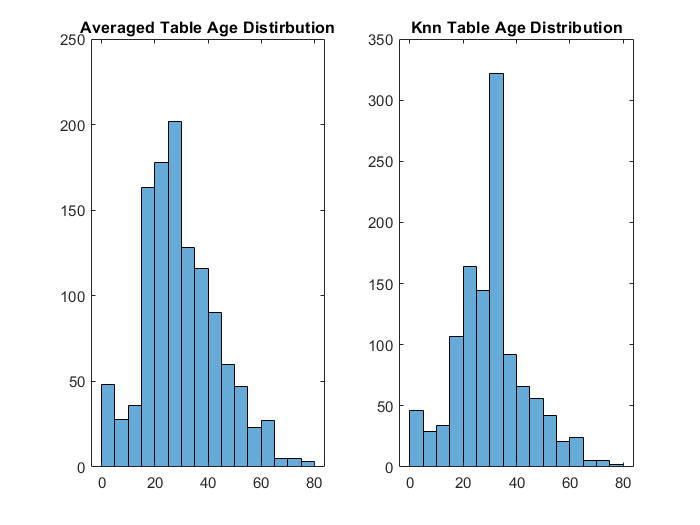

passengerData_nn.age = knnFlagTable.Var1;
passengerData_nn.fare = knnFlagTable.Var2;
passengerData_nn.embarked = knnFlagTable.Var3;
%Comprasion of difference between averaging and knnimpute function (Age)
figure,
subplot(121)
histogram(passengerData_av.age)
title('Averaged Table Age Distirbution')
subplot(122)
histogram(passengerData_nn.age)
title('Knn Table Age Distribution')

%Comprasion of difference between averaging and knnimpute function (Fare)
passengerData_nn(flagFareRw,flagFareCl)

ans = table
     fare 
    ______
    22.407

passengerData_av(flagFareRw,flagFareCl)

ans = table
     fare 
    ______
    11.252

nanmean(passengerData.fare(passengerData.pclass==3))

ans = 13.5883

%{
Pyhton Script
----------------------------
import numpy as np
import pandas as pd
from sklearn.impute import KNNImputer
headers = ['pclass','survived','age', 'sibsp','parch','fare']
Data = pd.read_csv("passengers_python.csv",usecols = headers)
Data = pd.DataFrame(Data)
imputer = KNNImputer(n_neighbors = 5)
d_filled = imputer.fit_transform(Data)
Data = np.array(d_filled)
pd.DataFrame(Data).to_csv(r'C:\Users\anili\PycharmProjects\titanicKnn\pyhtonKNNFile.csv',index = False, header = headers)
-----------------------------
%}
pyhtonKNNData = readtable("pyhtonKNNFile.csv")

pyhtonKNNData = 1159×6 table
    pclass    survived    age     sibsp    parch     fare 
    ______    ________    ____    _____    _____    ______
      1          1          29      0        0      211.34
      1          0           2      1        2      151.55
      1          0          30      1        2      151.55
      1          0          25      1        2      151.55
      1          1          48      0        0       26.55
      1          1          63      1        0      77.958
      1          0          39      0        0           0
      1          1          53      2        0      51.479
      1          0          71      0        0      49.504
      1          0          47      1        0      227.53
      1          1          18      1        0      227.53


pyhtonKNNData(flagFareRw,6)

ans = table
     fare 
    ______
    7.4933

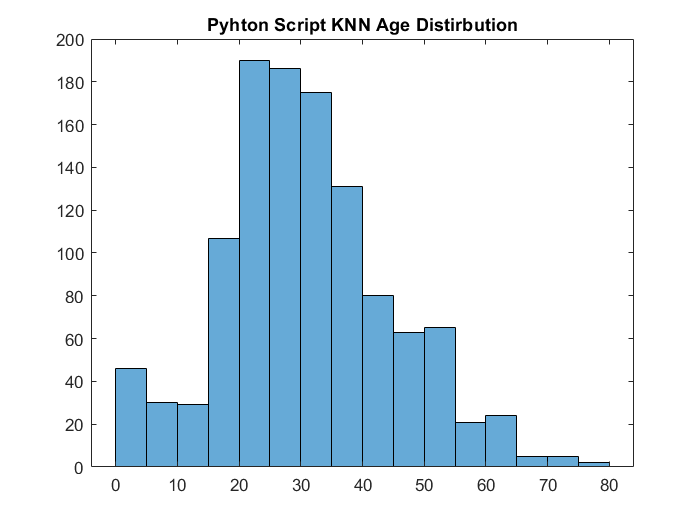

figure,
histogram(pyhtonKNNData.age)
title('Pyhton Script KNN Age Distirbution')

%Comprasion with Pyhton
idxNanArray = isnan(passengerData.age);
pyhtonImputedData = pyhtonKNNData.age(idxNanArray);
matlabKnnImputedData = passengerData_nn.age(idxNanArray);
NormalAgeData = passengerData.age(~idxNanArray)

NormalAgeData =     29
     2
    30
    25
    48
    63
    39
    53
    71
    47


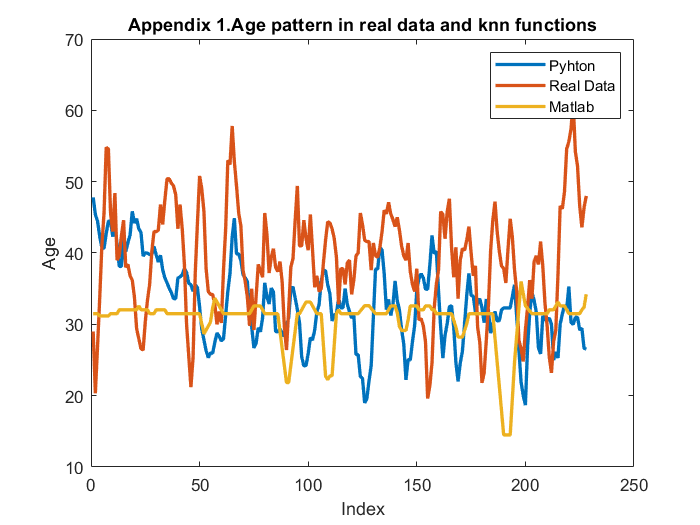

idxNumberPlot = 1:1:numel(pyhtonImputedData);
figure,
plot(idxNumberPlot,smooth(pyhtonImputedData),'Linewidth',2)
hold on
plot(idxNumberPlot,smooth(NormalAgeData(1:numel(idxNumberPlot))),'Linewidth',2)
hold on
plot(idxNumberPlot,smooth(matlabKnnImputedData),'Linewidth',2)
hold off
title('Appendix 1.Age pattern in real data and knn functions')
ylabel('Age')
xlabel('Index')
legend('Pyhton','Real Data','Matlab')

% I sampled the data does not contain nan-age value and I assume it is
% supposed to show same patterns.

3. In task 2 you may have noticed that there is one value missing from the `'fare'` attribute.  Compare your estimated values for the missing fare using the average approach and the nearest neighbour approach. Which do you think is more realistic given the other information about the passenger?

***In here , my fare values are very close to each other due to I used different method for averaging . However, when I use just averaging method (nanmean) I got the value of  33.6085, just put the knnfunction without playing with it I got the value of the 60.50, problem is starting here these this values is not realistic due to missing value at 1095 rowIdx , and the class is third (mean value of third class  13.58). Nan- mean averaging can be use due to still there are values of close to it. If I put k =  5 for knnimpute(), it will go for averaging nearest 5 cols , and in this case we are lucky cause nearest values are changing between 0 and 1 or max 8 therefore ,we can not detect any big mistake , but what if we have a thosund value that gives the birth year close to that row, it would probably wrong. If we return the first case, knn tends to get value from the nearest col which  left of the nan value which is 60.50 and age value. However, we need to take value from the nearest fare, therefore, we need to take transpose of the matrix.  After transpose, we got the value of 22.4 and I think it is more sensible when we compare with average of the fare in that class. In my case, I would use my averaging due to fact that age distribution is much more close our real distribution, but using knn impute is better than nanmean() function. ***

***Note : knnimpute() is better than nanmean() in that example. The reason for that our data is ordered. Therefore, knnimpute take the value in same class and it increases its accuracy. On the other hand, my averaging has a problem as well, the problem is we will see in the future it manipulates the threshold and all data. Here, the idea is that the value in the middle of the range will not significantly affect the prediction, therefore using nanmean() would be more accurate.***

***Note 2 :  I also used pyhton script to see how KNN impute works in pyhton. The problem is eucledian distance in Matlab defined function," ***you can add a row where every observation (column) has identical values and call `knnimpute` on the updated matrix to replace the NaN values with the average of all column values for a given row." **Because of this property effective value is not nearest one, effective value is determined by array that does not contain any Nan- value. Pyhton function can handle Nan values itself, we do not add any row that does not contain any Nan-Value.**

***Question 1:***

***Dear Proffessor,***

*** (defined knnimpute function uses  euclidean distance and it does not allow a Nan-Value in the row therefore we can not use that plain function and we need to change eucliden function if we had nan values in all col in data. Not taking tranpose also causes the distortion in age distribution cause age is assigned randomly from nearest row.  I just wonder what kind of approach would be better ? I used spearman but I do not know spearman automatically sort the data and it is generally used  better for categorical and ranked data. ***

***Thank you***

4. *Method 3: *In this case you will create new attributes that determine whether or not the data is missing. For example, you will create a new variable called  `'is_age_missing'`.  Generate a copy of the `passengerData` dataset, `passengerData_newAttr`, that contains new attributes indicating a missing value for the attributes `{'age', 'boat', 'body'}.  `These will be called `is_age_missing``, ``is_boat_missing`, and `is_body_missing `respectively.

passengerData_newAttr = passengerData;
passengerData_newAttr.is_age_missing = isnan(passengerData_newAttr.age); % 1-is missing, 0 - is not
passengerData_newAttr.is_boat_missing = ismissing(categorical(passengerData_newAttr.boat)); 
passengerData_newAttr.is_body_missing = isnan(passengerData_newAttr.body);

## Part 3: Computing entropy (25%)

### Tasks:

1. Write a function that takes as input an array containing data class (i.e. whether a passenger survived or not), and a list of all possible data classes ('survived' or 'not survived' here - represented by `1` or `0`), and computes the entropy.  It should have the following form:

This should be in a new file called *calcEnt.m* (or *calcEnt.mlx *if you prefer).  To check that it works, run the following:

testIn = categorical([1,1,1,1,0,0,0,0,1,0,0,0,0]);
classList = categories(testIn)

classList = 2×1 cell array
    {'0'}
    {'1'}

testCalcEnt = calcEnt(testIn,classList)

testCalcEnt = 0.9612

The result should be:

You may find the notes from Lectures 1 and 2 helpful.

2. a) Write another function that takes as input a continuous valued column of data, the associated data classes, and a threshold value and returns the information gain for splitting at that threshold.  Your function should have the following form:

This should be in a new file called *calcEntThresh.m* (or *calcEntThresh.mlx* if you prefer). Your code should call the `calcEnt` function you wrote in task 1 to calcuate the total entropy and the specific conditional entropy above and below the split. To confirm your code is correct, run the following:

ageData_test = [10,11,12,17,25,46,48,49,50];
dataClass_test = [0,0,0,1,1,1,0,0,0];
threshVal_test = 20;
testEnt = calcEntThresh(ageData_test,dataClass_test,threshVal_test)

testEnt = 0.0183

The result should be:

Next, run the following code on the age variable from your `nearestneighbour_av `data to compute the information gain for a threshold of 5:

ageData = passengerData_av.age;
dataClass = passengerData_av.survived;
threshVal = 5;
testEnt = calcEntThresh(ageData,dataClass,threshVal) %Different averaging caused this difference, I also added nanmean() averaging at the below and I got the value of 0.0073.

testEnt = 0.0061

The result should be:

b) Using your `calcEntThreshFunction`, plot the information gain when splitting on age at thresholds every 0.5 years from 0 to 100. The x-axis should be age threshold and the y-axis should be information gain.

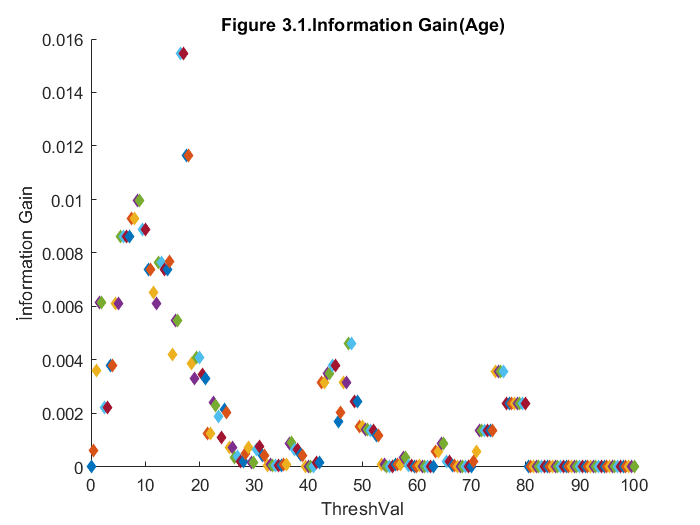

% Note my averaged data is different than nanmean(). Therefore information
% gain changed and the maximum information gain thresh val also changed.
figure,
for threshVal = 0:0.5:100
hold on
scatter(threshVal,calcEntThresh(ageData,dataClass,threshVal),'filled','d')
end
hold off
title('Figure 3.1.Information Gain(Age)')
xlabel('ThreshVal')
ylabel('İnformation Gain')

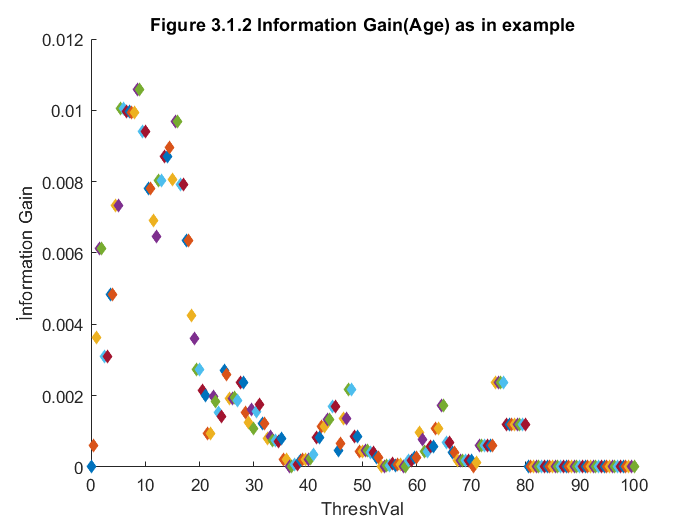

%nanmean() averaging gives the result that is supposed to be
tempAgeFile = 0;
for tempCounter = 1:1:n;
    if(isnan(passengerData.age(tempCounter)))
     tempAgeFile(tempCounter) = nanmean(passengerData.age);
    
    else
    tempAgeFile(tempCounter) = passengerData.age(tempCounter);
    end
end
figure,
for threshVal = 0:0.5:100
hold on
scatter(threshVal,calcEntThresh(tempAgeFile,dataClass,threshVal),'filled','d')
end
hold off
title('Figure 3.1.2 Information Gain(Age) as in example')
xlabel('ThreshVal')
ylabel('İnformation Gain')

calcEntThresh(tempAgeFile,dataClass,5) % Should be same : 0.0073

ans = 0.0073

%To find the age that gives the maximum information gain
detectionOfMaximumIG = calcEntThresh(ageData,dataClass,0);
%Figure 3.1 Max Value
for threshVal = 0:0.5:100
    functionFlag = calcEntThresh(ageData,dataClass,threshVal);
    if(detectionOfMaximumIG <= functionFlag )
         detectionOfMaximumIG = functionFlag;
         MaxIGThreshhold = threshVal;
    end
end
MaxIGThreshhold

MaxIGThreshhold = 17

detectionOfMaximumIG

detectionOfMaximumIG = 0.0155

detectionOfMaximumIG = calcEntThresh(ageData,dataClass,0);
%Figure 3.2 Max Value
for threshVal = 0:0.5:100
    functionFlag = calcEntThresh(tempAgeFile,dataClass,threshVal);
    if(detectionOfMaximumIG <= functionFlag )
         detectionOfMaximumIG = functionFlag;
         MaxIGThreshhold = threshVal;
    end
end
MaxIGThreshhold % It gives the age that contain maximum information gain

MaxIGThreshhold = 9

detectionOfMaximumIG

detectionOfMaximumIG = 0.0106

To the nearest year, what is the optimal threshold to split the `age` variable? Justify your answer.

***We should choose the threshold value where the information gain is the highest. First Case ; MaxIG  = 0.0155 where the age is 17. Second case, MaxIG = 0.0106 where the age is 9. Basically information gain gives the information as a bit.***

3. Write another function that takes as input a categorical valued column of data, the associated data classes, and an array of target categories. It should return the information gain for splitting the data into items that are in one of the target categories and items that are not. Your function should have the following form:

The `dataClass` variable will again be whether or not each data point 'survived'. The function should be in a new file called *calcEntCat.m* (or *calcEntCat.mlx* if you prefer). Your code should call the `calcEnt` function you wrote previously to calcuate the total entropy and the specific conditional entropy for each case. You might find the following function useful:

You may also find the following functions useful:

To test your function run the following code:

dataCat_test = {'dog','dog','cat','cat','cat','fish','fish','fish','fish'};
dataCat_test = categorical(dataCat_test);
dataClass_test = [1,0,1,0,1,0,1,0,1];
dataClass_check = {'fish'};
testEnt = calcEntCat(dataCat_test,dataClass_test,dataClass_check)

testEnt = 0.0072

The result should be:

Next, run your code on the `pclass` variable to compute the information gain for being in first class:

pclassData = passengerData_av.pclass;
dataClass = passengerData_av.survived;
pclassCheck = [1];
testEnt = calcEntCat(pclassData,dataClass,pclassCheck)

testEnt = 0.0568

The result should be 

4. Using your modified data table, `passengerData_newAttr`, for the attributes `{'sex', 'fare', 'ageMissing', 'boatMissing', 'bodyMissing'} `calculate which offers the highest information gain for the first split of a decision tree.  To test each variable you should find the maximum information gain across all target categories (for categorical variables) or across all threshold values for continuous variables.  You should use the functions you wrote for the previous tasks.

% Gender Information Gain
pclassData = passengerData_newAttr.sex;
dataClass = passengerData_newAttr.survived;
pclassCheck = 'female';
sexGain = calcEntCat(pclassData,dataClass,pclassCheck)

sexGain = 0.2078

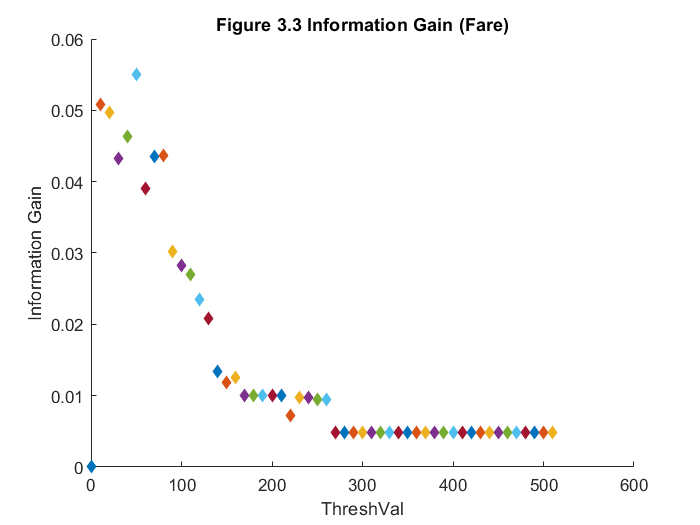

%Fare Information Gain
fareData = passengerData_av.fare;
dataClass = passengerData_av.survived;
threshValMax = max(passengerData_av.fare);
threshValMin = min(passengerData_av.fare);
% standartDevofThresh = std(passengerData_av.fare) / 10; We can also use
% standart deviation of passengerData_av.fare to detect an increase

figure,
tempFareMaxIG = 0;
tempFareMaxTresh = 0;
incresement = 10;
for threshVal = threshValMin:incresement:threshValMax
    temp = calcEntThresh(fareData,dataClass,threshVal);
        if (tempFareMaxIG <= temp )
                tempFareMaxIG = temp;
                tempFareMaxTresh = threshVal;
        end
scatter(threshVal,calcEntThresh(fareData,dataClass,threshVal),'filled','d')
hold on
end
hold off
title('Figure 3.3 Information Gain (Fare)')
ylabel('Information Gain')
xlabel('ThreshVal')

tempFareMaxTresh

tempFareMaxTresh = 50

tempFareMaxIG

tempFareMaxIG = 0.0551

%Age-Missing Information Gain
pclassData = passengerData_newAttr.is_age_missing;
dataClass = passengerData_newAttr.survived;
for pclassCheck = 0:1:1
pclassCheck
infoGain = calcEntCat(pclassData,dataClass,pclassCheck)
disp('--------------')
end

pclassCheck = 0

infoGain = 0.0084

--------------


pclassCheck = 1

infoGain = 0.0084

--------------


%Boat-Missing Information Gain
pclassData = passengerData_newAttr.is_boat_missing;
dataClass = passengerData_newAttr.survived;
for pclassCheck = 0:1:1
pclassCheck
infoGain = calcEntCat(pclassData,dataClass,pclassCheck)
disp('--------------')
end

pclassCheck = 0

infoGain = 0.7978

--------------


pclassCheck = 1

infoGain = 0.7978

--------------


% Checking the highest information gain (it makes sense or not)
SurvivorOfBotMissing = nnz(passengerData_newAttr.survived(passengerData_newAttr.is_boat_missing))

SurvivorOfBotMissing = 20

numberofBotMissing = nnz(passengerData_newAttr.is_boat_missing)

numberofBotMissing = 725

%Body-Missing Information Gain
pclassData = passengerData_newAttr.is_body_missing;
dataClass = passengerData_newAttr.survived;
for pclassCheck = 0:1:1
pclassCheck
infoGain = calcEntCat(pclassData,dataClass,pclassCheck)
disp('--------------')
end

pclassCheck = 0

infoGain = 0.0717

--------------


pclassCheck = 1

infoGain = 0.0717

--------------


%{
%Sibsp Information Gain
pclassData = passengerData_newAttr.sibsp;
dataClass = passengerData_newAttr.survived;
for pclassCheck = 0:1:numel(unique(pclassData))+1
pclassCheck
infoGain = calcEntCat(pclassData,dataClass,pclassCheck)
disp('--------------')
end 
%}

Which attribute provides the highest information gain?   Justify your answer.

***is_boat_missing provide us the highest information gain as it can be seen after line 550.***

What would you recommend to use for the first decision? Justify your answer.

***is_boat_missing provide us the the highest information, therefore I would pick that attribute if I just classify the titanic case. However, I would pick the sex(male or female) for future predictions , the reason for that the sex has the second highest information gain and I will  explain at below, why I would not pick is_boat_missing.***

Could `is_boat_missing` or `is_body_missing` realistically be used for prediction in future situations? Justify your answer.

***These attributes can not be used for prediction in future situations, because , the action already happened and this data obtained after the action happened. You can not get this information before the accident.***

***I also think that we can not predict the future using other attributes as well. I already mentioned what I think about the age. It is same for the fare, this accident happened 100 years ago. I might be wrong but , we might do something like, what kind of person is likely death paying more or paying less than average or generalization like A person paid more than 1000 people or B person paid less than 500 people. Probably it will depend on the number of the total passenger, but we can sample the data, I think it is easier than training the model everytime. For example,  we might use the distance of the each age to the distribution, but what if  ages are too close to each other, we need to scale it again. To sum up, I think predicting the future is tricky, everything would be different if we have data that contain all deadly cruise accident until today(probably it is just few, so we lack of the data).***

### Part 4: From Decision Trees to Random Forests (25%)

In real applications, we don't typically code our own entropy computation functions from scratch - we instead exploit the multitude of pre-existing libraries.  Here, you will train decision trees and random forests using MATLAB's Statistics and Machine Learning Toolbox.

### Tasks

1. First, use the `cvpartition` function to split your data up into several possible 'training' and 'validation' sets

[n,m] = size(passengerData);
dataClass = ones(n,1);
c = cvpartition(dataClass,'KFold',10); %10-fold cross validation set
trainIdxes = training(c,1); %Just use the first of the 10 splits
valIdxes = test(c,1);
nnz(trainIdxes);
nnz(valIdxes);

This performs a 10-fold split of data, i.e. the data is split into training and validation in 10-different non-overlapping ways. Initially, we will just use the first of these splits to fit our decision tree.

a) Take your `passengerData_newAttr` dataset generated in Part 2 and remove all attributes except `{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'ageMissing'}` to create a new dataset `passengerData_newAttr_partial`*. *You may find the following functions useful:

[n,m] =size(passengerData_newAttr);
passengerData_newAttr_partial = passengerData_newAttr;
for colIdx = 1:m   
   
   if (passengerData_newAttr.Properties.VariableNames{colIdx} == "pclass" || passengerData_newAttr.Properties.VariableNames{colIdx} == "embarked"  )
   elseif (passengerData_newAttr.Properties.VariableNames{colIdx} == "sex" || passengerData_newAttr.Properties.VariableNames{colIdx} == "age" )
   elseif (passengerData_newAttr.Properties.VariableNames{colIdx} == "sibsp" || passengerData_newAttr.Properties.VariableNames{colIdx} == "parch" )
   elseif (passengerData_newAttr.Properties.VariableNames{colIdx} == "fare" ||  passengerData_newAttr.Properties.VariableNames{colIdx} == "is_age_missing")
   else
       flagString = passengerData_newAttr.Properties.VariableNames{colIdx};
       passengerData_newAttr_partial = removevars(passengerData_newAttr_partial,flagString) ; 
   end
end
%passengerData_newAttr_partial

b) Next, split `passengerData_newAttr_partial` and the corresponding data classes into a training and validation set (`passengerData_newAttr_train` and `dataClass_train` respectively) using the `trainIdxes` and `valIdxes` arrays generated above.

passengerData_newAttr_train = passengerData_newAttr_partial(trainIdxes,:);
passengerData_newAttr_validation = passengerData_newAttr_partial(valIdxes,:);
survivedOrNot_train_information = passengerData.survived(trainIdxes);

%{
pclass_train = passengerData_newAttr_train.pclass;
age_train = passengerData_newAttr_train.age;
sex_train = grp2idx(categorical(passengerData_newAttr_train.sex));
sibsp_train = passengerData_newAttr_train.sibsp;
parch_train = passengerData_newAttr_train.parch;
fare_train = passengerData_newAttr_train.fare;
embarked_train = grp2idx(categorical(passengerData_newAttr_train.embarked));
age_missing_train = passengerData_newAttr_train.is_age_missing;
arrayTrain = [pclass_train,age_train,sex_train,sibsp_train,parch_train,fare_train,embarked_train,age_missing_train]
%}

c) Now fit a decision tree using the `fitctree` function and plot it using the `view` function with the name-value argument `'Mode', 'graph'`.  *Note*: you must tell the fitting algorithm which variables are 'categorical', otherwise it assumes all are continuous valued - this can be done using the `'CategoricalPredictors'` argument.

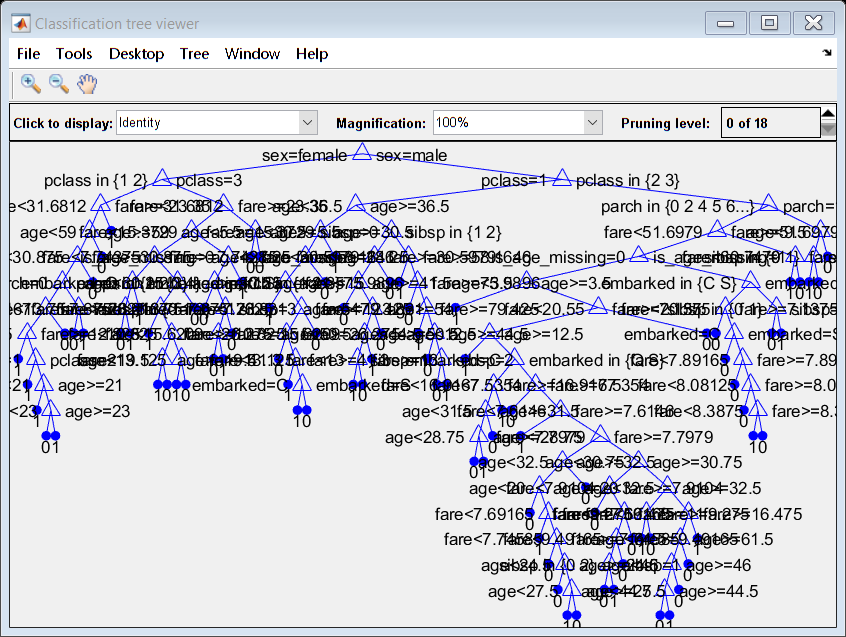


t = fitctree(passengerData_newAttr_train,survivedOrNot_train_information,'CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked','is_age_missing'});
view(t,'Mode','graph');

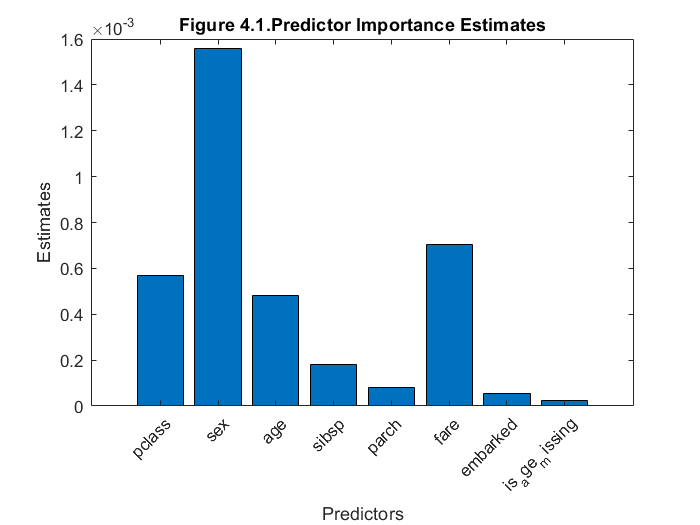

importance_graph = predictorImportance(t);
figure;
bar(importance_graph);
title('Figure 4.1.Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = t.PredictorNames;
h.XTickLabelRotation = 45;

Looking at the tree, what are the first, second and third most important attributes for determining survival? Justify your answer. You might find it helpful to look up the following function in the MATLAB help:

***As it is seen in Figure 4.1, the first important attributes is sex, the second is fare and the third age.***

d) Use the *predict* method on the validation set.  For example:

Compute the classification accuracy on the validation set.

%{
pclass_val = passengerData_newAttr_validation.pclass;
age_val = passengerData_newAttr_validation.age;
sex_val = grp2idx(categorical(passengerData_newAttr_validation.sex));
sibsp_val = passengerData_newAttr_validation.sibsp;
parch_val = passengerData_newAttr_validation.parch;
fare_val = passengerData_newAttr_validation.fare;
embarked_val = grp2idx(categorical(passengerData_newAttr_validation.embarked));
age_missing_val = passengerData_newAttr_validation.is_age_missing;
arrayVal = [pclass_val,age_val,sex_val,sibsp_val,parch_val,fare_val,embarked_val,age_missing_val]
%}
survivedOrNot_val_information = passengerData.survived(valIdxes);
t.predict(passengerData_newAttr_validation)

ans =      0
     0
     0
     0
     1
     1
     1
     1
     1
     1


accuracy = nnz((t.predict(passengerData_newAttr_validation) == survivedOrNot_val_information)) / numel(survivedOrNot_val_information)

accuracy = 0.7478

2. a) You will now 'prune' your tree. To limit the size of your tree use the '`MaxNumSplits'` name-variable option - consult the MATLAB documentation on `fitctree` for more information.  Try different values for `MaxNumSplits` from 1 to 200 and produce a plot that shows how the classification accuracy changes for both the training and validation sets.  That is, you should produce a plot of classification accuracy vs. MaxNumSplits containing two curves: training data and validation data.  

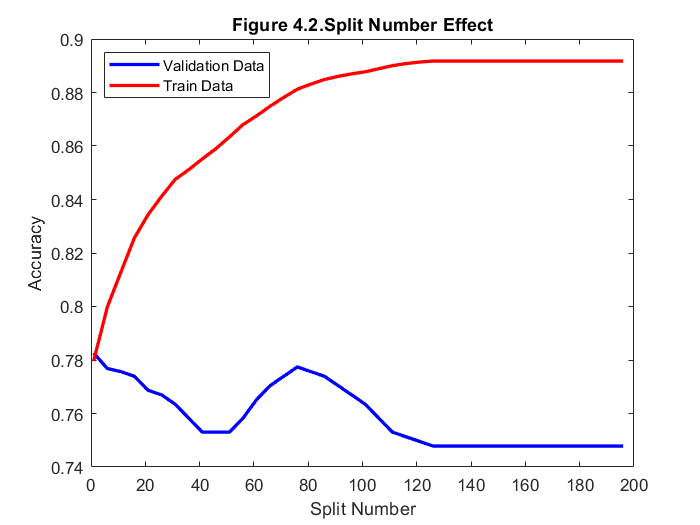

figure;
accuracyFlag = 0;
maxAccuracy = 0;
maxAccuracySplitNumber = 0;
innerCounter = 1;
for numberOfSplits = 1:5:200
Model = fitctree(passengerData_newAttr_train,survivedOrNot_train_information,'MaxnumSplits',numberOfSplits,'CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked','is_age_missing'});
accuracy_val(innerCounter) = nnz((Model.predict(passengerData_newAttr_validation) == survivedOrNot_val_information)) / numel(survivedOrNot_val_information);
accuracy_train(innerCounter) = nnz((Model.predict(passengerData_newAttr_train) == survivedOrNot_train_information)) / numel(survivedOrNot_train_information);

if(maxAccuracy < accuracy_val(innerCounter))
    maxAccuracy = accuracy_val(innerCounter);
    maxAccuracySplitNumber = numberOfSplits;
end
innerCounter = innerCounter + 1;
end
xl = 1:5:200;
plot(xl,smooth(accuracy_val),'b','LineWidth',2)
hold on
plot(xl,smooth(accuracy_train),'r','LineWidth',2)
hold off
legend('Validation Data','Train Data','Location','northwest')
xlabel('Split Number')
ylabel('Accuracy')
title('Figure 4.2.Split Number Effect')

Based on this graph, what you recommend as a sensible value for `MaxNumSplits`*?* Justify your answer.

***As it is expected, when the number of split increases, overfitting occurs (performance in test data is significantly high, while prediction for validation set shows poor performance). Therefore, prune the decision tree (generalization) help us to achieve higher accuracy. This graph is changing all the time due to change in train and validation set therefore, it is really hard to say exact point but I would choose below the 20 splits and above the 5 splits. ***

b) You may notice that if you run your code multiple times, the graph is quite different - this is due to the fact that the `cvpartition` function randomly splits up the data in a different way each time.  A more robust approach is to perform a k-fold cross validation - i.e. produce *k* different splits, calculate the accuracy of each when predicting the training set and then plot the average across the *k* splits.  Modify your code above to use the `CrossVal` method (see documentation for `fitctree`) then plot the accuracy of the k-fold cross-validated model using the `kfoldLoss` function.

%Max Accuracy
maxAccuracy

maxAccuracy = 0.7826

%Split Number
maxAccuracySplitNumber

maxAccuracySplitNumber = 1

DetectednumberOfSplits = 20 % that might be different value but should be less than 25

DetectednumberOfSplits = 20

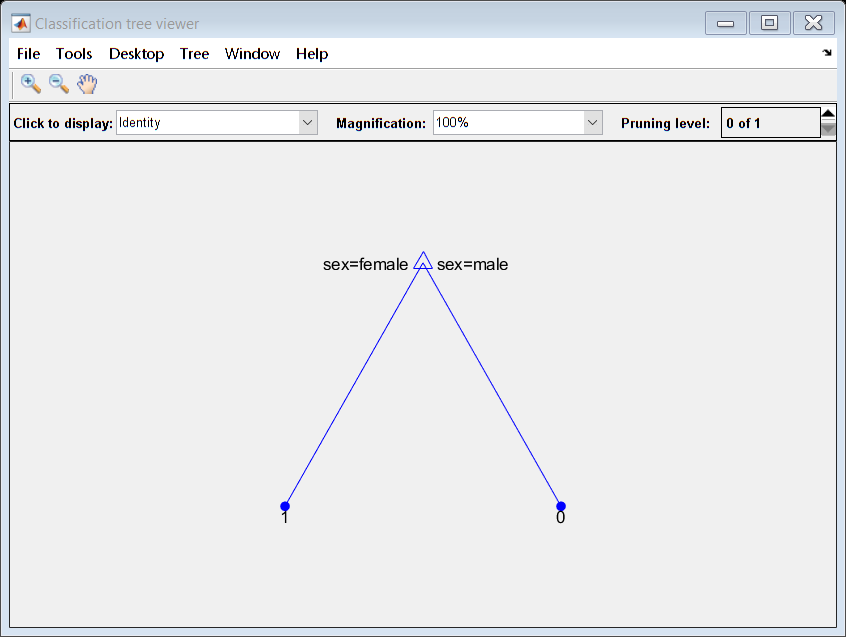

%How Pruned Tree look like
Model = fitctree(passengerData_newAttr_train,survivedOrNot_train_information,'MaxnumSplits',maxAccuracySplitNumber,'CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked','is_age_missing'});
view(Model,'Mode','graph');

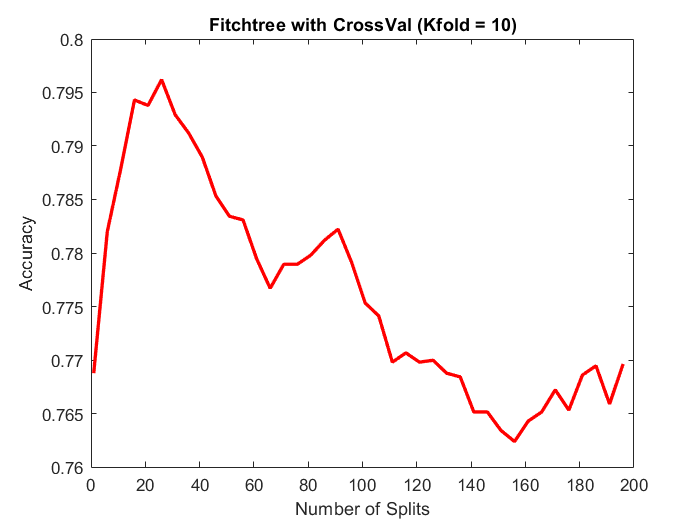


k = 1;
for i = 2:5:200
model = fitctree(passengerData_newAttr_partial,passengerData_newAttr.survived,'MaxnumSplits',i,'CrossVal','on','CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked','is_age_missing'});
modelError = kfoldLoss(model);
modelAc(k) = 1-modelError;
k = k + 1;
end
x = 1:5:200;
figure,
plot(x,smooth(modelAc),'r','LineWidth',2)
title('Fitchtree with CrossVal (Kfold = 10)')
xlabel('Number of Splits')
ylabel('Accuracy')

Based on this graph, what you recommend as a sensible value for `MaxNumSplits`? Justify your answer.

***Actually , Cross Val seperate the data equally, and train the data.  I recommended to set our number of splits between 20 splits and 25 splits. I think this range is more reliable due to fact that cross valudation seperate data train and  take the average.***

Which of these two estimates would you recommend using for building a model? Justify your answer.

***We should be aware of  not choose  a higher  number of the split that cause overfitting  and using the  cross validation for avoiding from overfitting as well. ***

***Splits = 20 - 25 , Cross Val 'on'***

3. Next, we will move from using decision trees to using random forests.  To this, we will use the `TreeBagger` class, which creates a specified number of random trees.  For example:

a) Write code that generates random forests with different numbers of trees, ranging from 1 to 80 trees, and determines the classification error on the validation set in each case. Plot a graph of validation error vs. number of trees in the forest.

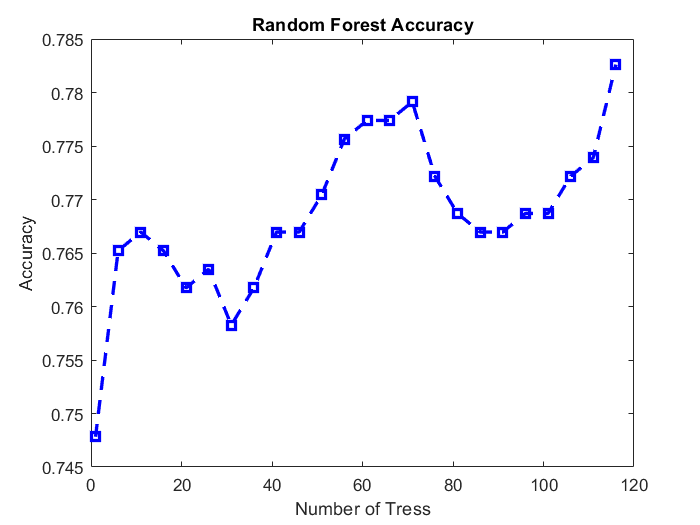

counter = 1;
accuracyForest = 0;
for nTress = 1:5:120
dataClass_train = survivedOrNot_train_information;
f = TreeBagger(nTress,passengerData_newAttr_train,dataClass_train,'Method','classification', 'CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked','is_age_missing'});
accuracyForest(counter) = nnz(str2double(f.predict(passengerData_newAttr_validation)) == survivedOrNot_val_information) / numel(survivedOrNot_val_information);
counter = counter + 1 ;
end
k = 1:5:120;
figure,
plot(k,smooth(accuracyForest),'--bs','Linewidth',2)
title('Random Forest Accuracy')
xlabel('Number of Tress')
ylabel('Accuracy')

What do you think is the best size of forest to use? Justify your answer.

***I recommed the sensible number of trees. Higher number of trees provide us higher accuracy. However, if we increase it too much for example over 1000 or 2000, we will not see any big difference in accuracy between this two value, but using 2000 trees ends up with much more traning time. Thefore, it better to choose where it is breakdown point in error. I mean after some point accuracy will be almost constant, and which is the lowest number gives the same accuracy can be choosen. In our case, graph is changing but it often changes  between 20 and 80 with 0.02 and 0.03, I mean there is no big difference. I can not say exact number, but it is critical to choose above  20. ***

b) Instead of testing on the validation set, which wastes data as it can't be used for training, you can do something similar to cross-validation that involves testing each tree in the forest on 'out-of-bag' data, i.e. data points that were not used in training that particular tree.  Plot the out-of-bag error vs. number of trees in the forest for values 1 to 80. You may find the following function useful:

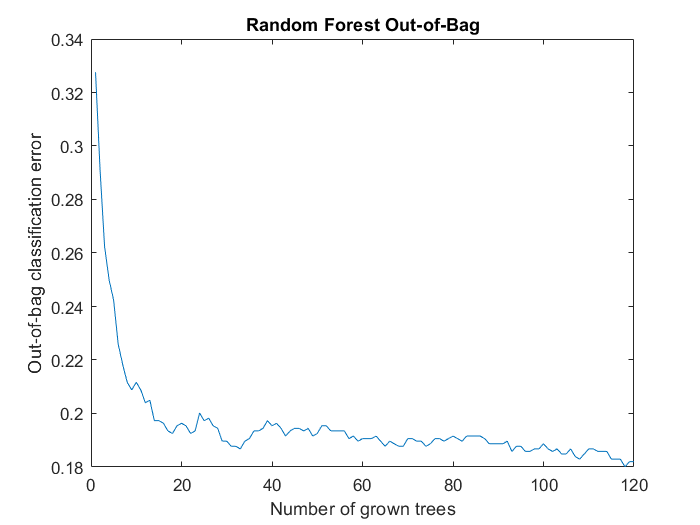

nTress = 120;
f = TreeBagger(nTress,passengerData_newAttr_train,dataClass_train,'OOBPrediction','On','Method','classification','OOBPredictorImportance','on','CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked','is_age_missing'});
oobErrorBaggedEnsemble = oobError(f);
figure,
plot(oobErrorBaggedEnsemble)
xlabel 'Number of grown trees';
ylabel 'Out-of-bag classification error';
title('Random Forest Out-of-Bag')

Based on the out-of-bag error, what do you think is the best size of tree to use? Justify your answer.

***As we discussed before, we can see the decrease in error by increasing trees. Cross Validation provide us more general view of number of trees effect on acccuracy. I will choose 120 , the reason for that it will not effect my computation time critically, while giving me a little bit higher accuracy. Also we can use little above 20 where is the breakdown point, but choosing 120 gives us a little safety margin.***

4. a) Using the methods you have developed so far, write code that trains a Random Forest classifier on the full data set in the file passengers.csv and then takes in a second file, passengersVal.csv, that does not contain any survival variable, and performs predictions of survival on these data points. A sample passengersVal.csv file (containing data already in the training set) has been provided. For marking a different data file, containing passenger data not in the original passengers.csv file, will be used to test how well your Random Forest classifer predicts survival. For training and prediction use only the following attributes: `{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked'}`. To be clear, your final code must read in and perform prediction on the passengersVal.csv file.

passengersValData = readtable('passengersVal.csv')

passengersValData = 150×13 table
    pclass                                 name                                     sex        age    sibsp    parch       ticket        fare        cabin       embarked       boat       body                 home_dest              
    ______    _______________________________________________________________    __________    ___    _____    _____    ____________    ______    ___________    ________    __________    ____    ____________________________________
      1       {'Allison, Miss. Helen Loraine'                

[n,m] =size(passengerData);
passengerData_forest = passengerData

passengerData_forest = 1159×14 table
    pclass    survived                            name                                sex        age    sibsp    parch       ticket        fare        cabin       embarked       boat       body                 home_dest             
    ______    ________    _____________________________________________________    __________    ___    _____    _____    ____________    ______    ___________    ________    __________    ____    ___________________________________
      1          1   

for colIdx = 1:m   
   
   if (passengerData.Properties.VariableNames{colIdx} == "pclass" || passengerData.Properties.VariableNames{colIdx} == "embarked" )
   elseif (passengerData.Properties.VariableNames{colIdx} == "sex" || passengerData.Properties.VariableNames{colIdx} == "age" )
   elseif (passengerData.Properties.VariableNames{colIdx} == "sibsp" || passengerData.Properties.VariableNames{colIdx} == "parch" )
   elseif (passengerData.Properties.VariableNames{colIdx} == "fare")
   else
       flagString = passengerData.Properties.VariableNames{colIdx};
       passengerData_forest = removevars(passengerData_forest,flagString) ; 
   end
end
passengerData_forest

passengerData_forest = 1159×7 table
    pclass       sex        age    sibsp    parch     fare     embarked
    ______    __________    ___    _____    _____    ______    ________
      1       {'female'}     29      0        0      211.34     {'S'}  
      1       {'female'}      2      1        2      151.55     {'S'}  
      1       {'male'  }     30      1        2      151.55     {'S'}  
      1       {'female'}     25      1        2      151.55     {'S'}  
      1       {'male'  }     48      0        0       26.55     {'S'}  
      1       {'female'}     63      1        0      77.958     {'S'}  
      1       {'male'  }     39      0        0           0     {'S'}  
      1       {'female'}     53      2        0      51.479     {'S'}  
      

f = TreeBagger(120,passengerData_forest,passengerData.survived,'Method','classification','OOBPredictorImportance','on','MaxNumSplits',20,'CategoricalPredictors',{'pclass','sex','sibsp','parch','embarked'});
predictions = str2double(f.predict(passengersValData))

predictions =      1
     1
     0
     1
     1
     1
     1
     1
     0
     1


b) For your trained Random Forest, what are the most important attributes?  To find this out, you may may wish to use the following flags:

figure;
impCART = f.OOBPermutedPredictorDeltaError

impCART =     1.5948    4.5313    0.9842    0.5416    0.7511    1.0653    0.2179


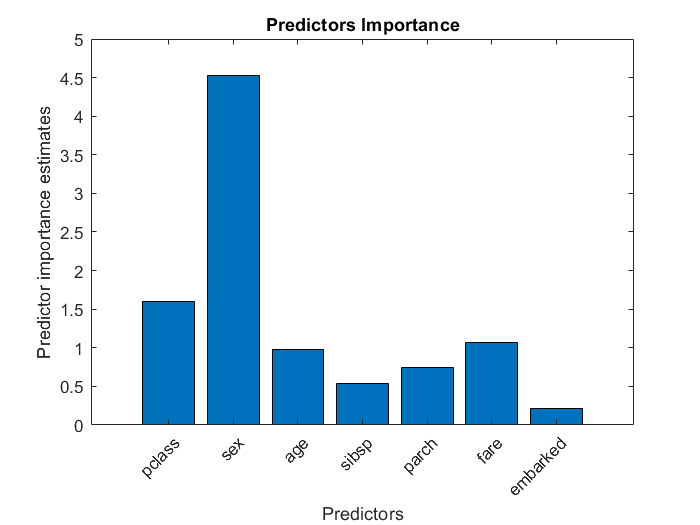

lastBar=bar(impCART);
title('Predictors Importance')
ylabel('Predictor importance estimates')
xlabel('Predictors')
h = gca;
h.XTickLabel = f.PredictorNames;
h.XTickLabelRotation = 45;

Comment on your answer.

***Large estimate value indicates predictor that have a greater influence on prediction. In our case, sex is the most important predictor following by pclass,fare and age.***